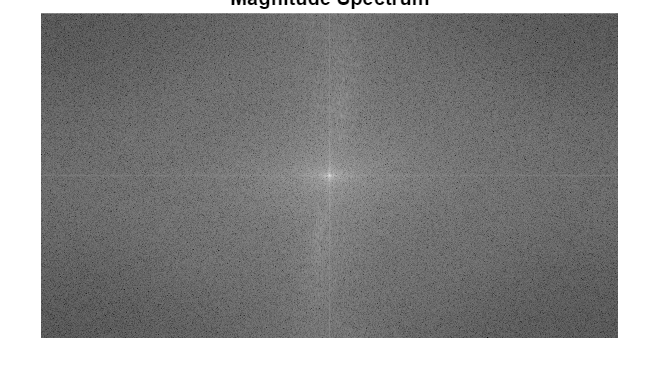

% Step 1: Read the image into the workspace
img1 = imread('C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Assignment 4\pic1.png'); % Replace with your image path
img1 = rgb2gray(img1); % Convert to grayscale if it's a color image

% Step 2: Apply Fourier transform to img1
F_img1 = fft2(double(img1));
F_img1_shifted = fftshift(F_img1); % Shift the zero-frequency component to the center

% Step 3: Display both frequency and phase matrix as images
magnitude_spectrum = log(1 + abs(F_img1_shifted)); % Use log transform for better visualization
phase_spectrum = angle(F_img1_shifted);

figure, imshow(magnitude_spectrum, []), title('Magnitude Spectrum');

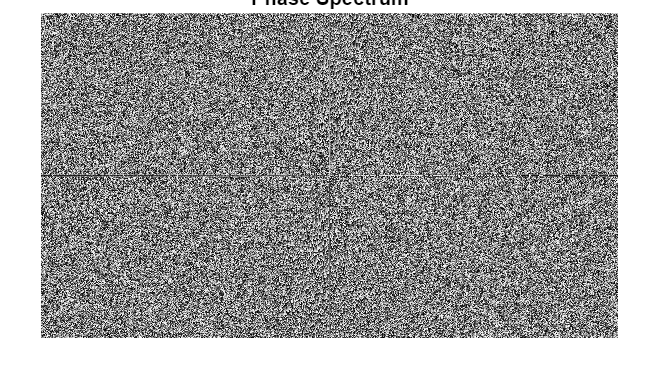

figure, imshow(phase_spectrum, []), title('Phase Spectrum');

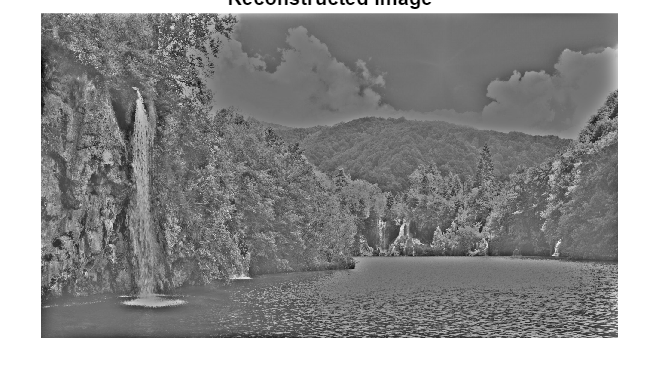


% Step 4: Remove the low-frequency components
% Create a mask with a high-pass filter (e.g., Gaussian)
[m, n] = size(F_img1_shifted);
[X, Y] = meshgrid(1:n, 1:m);
centerX = round(n/2);
centerY = round(m/2);
sigma = 10; % Width of the Gaussian low pass filter, adjust as needed
GaussianFilter = exp(-((X-centerX).^2 + (Y-centerY).^2) / (2*sigma^2));
HighPassFilter = 1 - GaussianFilter;

% Apply the high-pass filter
F_img1_highpass = F_img1_shifted .* HighPassFilter;

% Step 5: Reconstruct the image from the new Fourier coefficient matrix
F_img1_highpass = ifftshift(F_img1_highpass); % Shift back to original
imgR = real(ifft2(F_img1_highpass)); % Inverse Fourier transform

% Display the reconstructed image imgR
figure, imshow(imgR, []), title('Reconstructed Image');

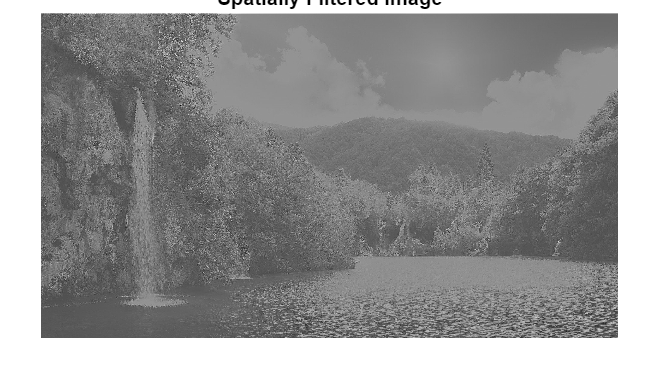


% Step 6: Construct and apply a spatial filter to img1 to match imgR
% Here we'll create a simple sharpening filter that enhances high-frequency
% components, similar to the effect of the high-pass filter in frequency domain
h = fspecial('unsharp');
imgFiltered = imfilter(double(img1), h);

% Display the spatially filtered image
figure, imshow(imgFiltered, []), title('Spatially Filtered Image');


% Step 7: Compute and display the similarity score
% We will use the Peak Signal-to-Noise Ratio (PSNR) as the similarity measure
peaksnr = psnr(imgFiltered, imgR);

fprintf('The Peak-SNR between the spatially filtered image and reconstructed image is: %0.4f dB\n', peaksnr);

The Peak-SNR between the spatially filtered image and reconstructed image is: -44.0327 dB
